## Creamos el Robot.

Se busca en las conexiones USB y se espera el comando.

Robot = ArduinoManager();

Initializing Arduino Manager...
Scanning ports: /dev/ttyS15, /dev/ttyS6, /dev/ttyS23, /dev/ttyS13, /dev/ttyS31, /dev/ttyS4, /dev/ttyS21, /dev/ttyS11, /dev/ttyS2, /dev/ttyS28, /dev/ttyS0, /dev/ttyS18, /dev/ttyS9, /dev/ttyS26, /dev/ttyS16, /dev/ttyACM0, /dev/ttyS7, /dev/ttyS24, /dev/ttyS14, /dev/ttyS5, /dev/ttyS22, /dev/ttyS12, /dev/ttyS30, /dev/ttyS3, /dev/ttyS20, /dev/ttyS10, /dev/ttyS29, /dev/ttyS1, /dev/ttyS19, /dev/ttyS27, /dev/ttyS17, /dev/ttyS8, /dev/ttyS25
Probing /dev/ttyS15... Error accessing port.
Probing /dev/ttyS6... Error accessing port.
Probing /dev/ttyS23... Error accessing port.
Probing /dev/ttyS13... Error accessing port.
Probing /dev/ttyS31... Error accessing port.
Probing /dev/ttyS4... No response.
Probing /dev/ttyS21... Error accessing port.
Probing /dev/ttyS11... Error accessing port.
Probing /dev/ttyS2... Error accessing port.
Probing /dev/ttyS28... Error accessing port.
Probing /dev/ttyS0... No response.
Probing /dev/ttyS18... Error accessing port.
Probing /dev/tt

## Inicialización.

Moviendo los servos a 90º

Robot.setServos(0, 0);

Method 'setServos' is not defined for class 'ArduinoManager' or is removed from MATLAB's search path.

## Posiciones nuevas

Con los "sliders" puedes seleccionar las nuevas posiciones del robot.

P1 = -50

P1 = -50

P2 = 10

P2 = 10

## Enviar comando

Robot.setServos(P1, P2);
[x, y] = cinem_directa_analitica(P1, P2)

x = 13.5820

y = -13.8902

[xd, yd] = cinematica_DH(P1, P2)

xd = 13.5820

yd = -13.8902

## Actualización continua

Con los "sliders" puedes seleccionar las nuevas posiciones del robot.

P1 = -46;
P2 = -38;
Robot.setServos(P1, P2);

 

## Cinemática directa y espacio de trabajo

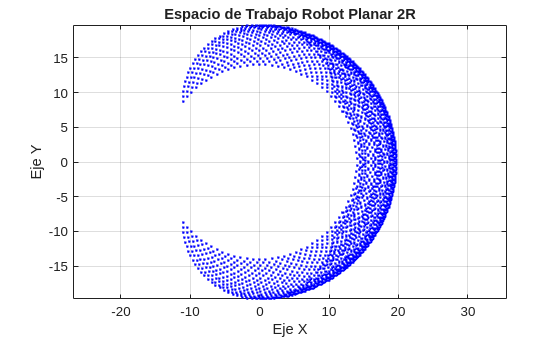

EspacioDeTrabajo(8.75, 11);

## Uso de la cinemática inversa

Introduce las coordenadas X, Y deseadas. 

Asegurate que pertenezcan al espacio de trabajo!

X = 15.1        

X = 15.1000

Y = -2

Y = -2

[P1, P2] = ik_geometrica(X, Y, 11, 8.75)

P1 = 26.8699

P2 = -79.6915

Robot.setServos(P1, P2);
 